# **Clustering IRIS Dataset**

#### **by: Naeem Khoshnevis**

#### **Last Update: June 7, 2022**

#### **Summary**

We present steps to cluster the Iris data set. The Iris data set is one of the most used data sets to study pattern recognition. The data set is created by R. A. Fisher. The dataset includes three different classes of flowers: Iris Setosa, Iris Versicolour, and Iris Virginica. These classes can be categorized based on their sepal length, sepal width, petal length, and petal width. We use the k-means clustering algorithm to cluster these flowers. The k-means clustering starts from random cluster centers and can provide different clusters for different runs. We take the necessary steps to make the processing reproducible. 

#### **Data**

The Iris data can be downloaded from the UC Irvine Machin Learning Repository (https://archive.ics.uci.edu/ml/datasets/iris). Here is the link of download. 

- [https://archive.ics.uci.edu/ml/machine-learning-databases/iris/iris.data](https://archive.ics.uci.edu/ml/machine-learning-databases/iris/iris.data) 

More information about the data can be downloaded from the following link.

- [https://archive.ics.uci.edu/ml/machine-learning-databases/iris/iris.names](https://archive.ics.uci.edu/ml/machine-learning-databases/iris/iris.names) 

We put a copy of these files inside the `data` folder. 

data = readtable("data/iris.csv", 'Format','%f%f%f%f%s');
varNames = {'sepal length','sepal width','petal length','petal width', 'class'};
data.Properties.VariableNames = varNames;
head(data)

ans = 8×5 table
    sepal length    sepal width    petal length    petal width         class     
    ____________    ___________    ____________    ___________    _______________

        5.1             3.5            1.4             0.2        {'Iris-setosa'}
        4.9               3            1.4             0.2        {'Iris-setosa'}
        4.7             3.2            1.3             0.2        {'Iris-setosa'}
        4.6             3.1            1.5             0.2        {'Iris-setosa'}
          5             3.6            1.4             0.2        {'Iris-setosa'}
        5.4             3.9            1.7             0.4        {'Iris-setosa'}
        4.6             3.4            1.4             0.3        {'Iris-setosa'}
          5             3.4            1.5             0.2        {'Iris-se

% convert features table to matrix
feature_mat = data{:,1:4}

feature_mat =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


Now, we can take a look at data.

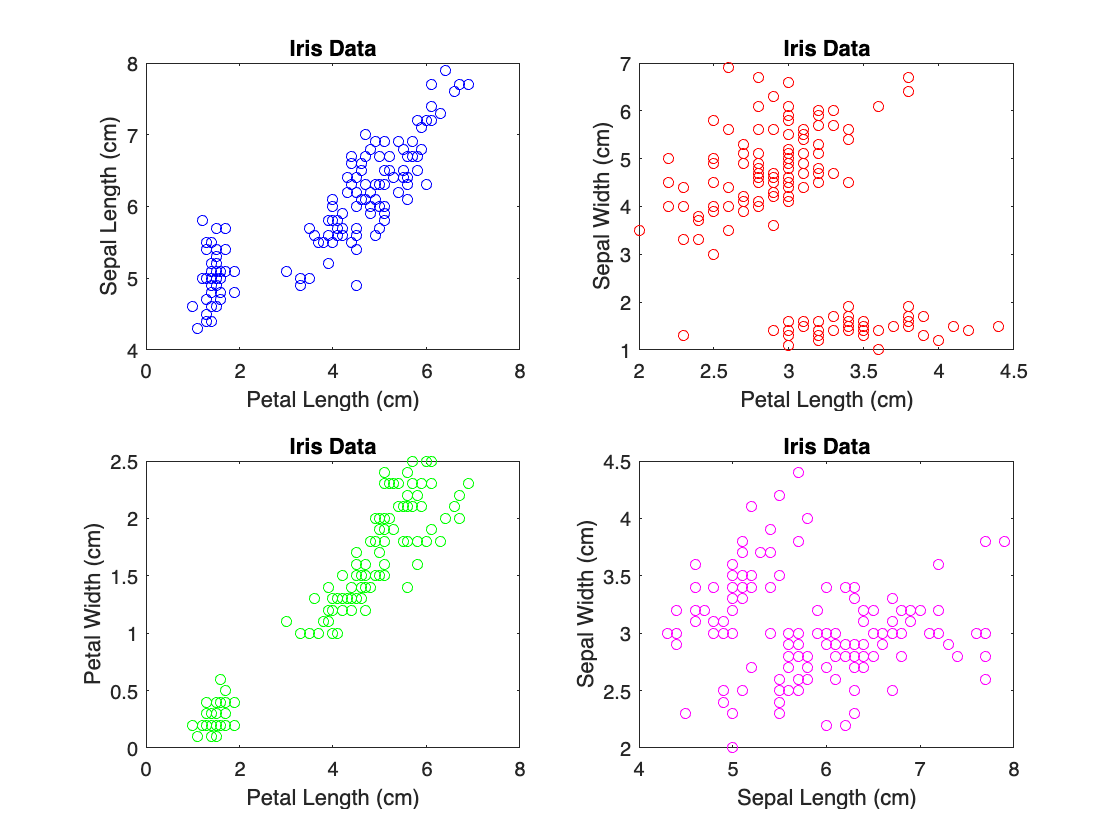

figure;
subplot(2,2,1)
plot(feature_mat(:,3),feature_mat(:,1),'bo', 'MarkerSize',5);
title('Iris Data')
xlabel('Petal Length (cm)');
ylabel('Sepal Length (cm)');


subplot(2,2,2)
plot(feature_mat(:,2),feature_mat(:,3),'ro', 'MarkerSize',5);
title('Iris Data')
xlabel('Petal Length (cm)');
ylabel('Sepal Width (cm)');


subplot(2,2,3)
plot(feature_mat(:,3),feature_mat(:,4),'go', 'MarkerSize',5);
title('Iris Data')
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');


subplot(2,2,4)
plot(feature_mat(:,1),feature_mat(:,2),'mo', 'MarkerSize',5);
title('Iris Data')
xlabel('Sepal Length (cm)');
ylabel('Sepal Width (cm)');

#### k-means Clustering

In the k-means algorithm, we need to decide on the number of clusters. Estimating the number of clusters based on the study data is beyond the scope of this summary. We use the number of unique classes as a number of clusters.  Let's say we want to cluster data based on `petal length` and `sepal lenght`. 

rng(123); % For reproducibiliy
n_cluster = 3;
[idx, C] = kmeans(feature_mat(:,[1,3]),n_cluster);

`C` represents the cluster centers and idx is the vector of corresponding predicted clusters. Let's take a look at hte results on a figure. 

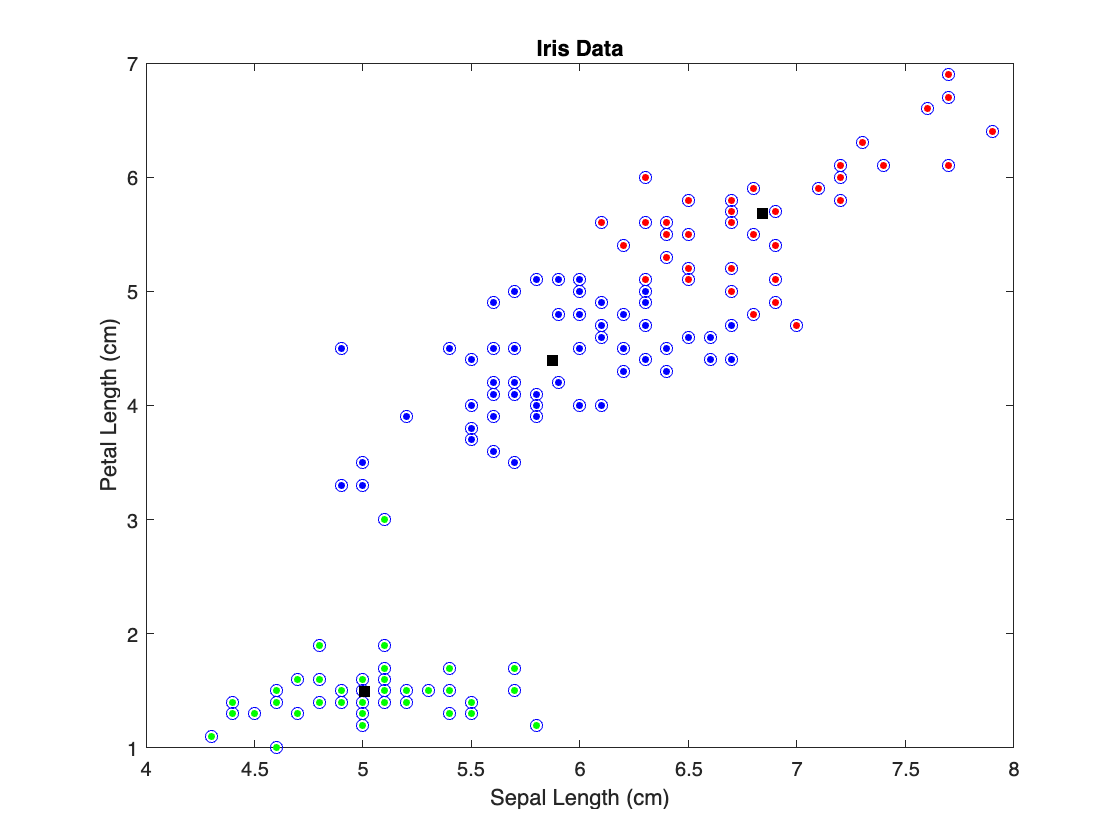

% Create a color matrix. 
color_mat = (idx==1)*[1 0 0] + (idx==2)*[0 1 0] + (idx==3)*[0 0 1];

figure;
plot(feature_mat(:,1), feature_mat(:,3), 'bo')
hold on
scatter(feature_mat(:,1), feature_mat(:,3), 12, color_mat, 'filled')
scatter(C(:,1), C(:,2), 48, 'black','filled','square')
title('Iris Data')
xlabel('Sepal Length (cm)');
ylabel('Petal Length (cm)');

In the figure, hollow circles represent the original data, color-filled circles represent the clusters, and black-filled squares represent the cluster center. 

#### Saving Output

We store the output data in the `output` folder. 

writematrix(C, "output/cluster_centers.csv")
writematrix(idx, "output/cluster_index.csv")

Done!

#### Computing Environment

ver

-----------------------------------------------------------------------------------------------------
MATLAB Version: 9.12.0.1956245 (R2022a) Update 2
MATLAB License Number: 596681
Operating System: macOS  Version: 11.2 Build: 20D64 
Java Version: Java 1.8.0_202-b08 with Oracle Corporation Java HotSpot(TM) 64-Bit Server VM mixed mode
-----------------------------------------------------------------------------------------------------
MATLAB                                                Version 9.12        (R2022a)
Statistics and Machine Learning Toolbox               Version 12.3        (R2022a)
